# Матрицы

### Линейная зависимость: одномерный случай

### 
$$y=a\cdot x$$


x = linspace(-3,3);
y = 3*x;
plot(x,y,'LineWidth',3)

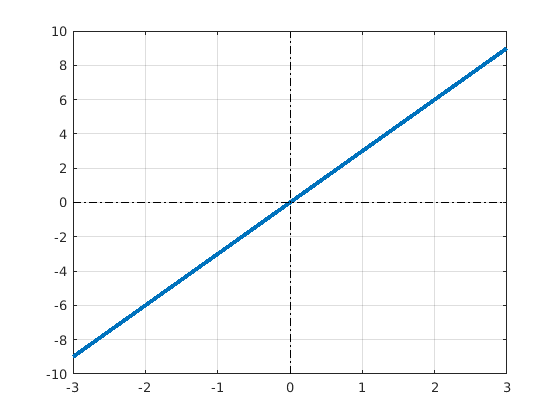

hold on, grid on
plot([0 0], ylim,'k-.')
plot(xlim, [0 0],'k-.')
hold off

## 
$$a:R^1 \to R^1$$


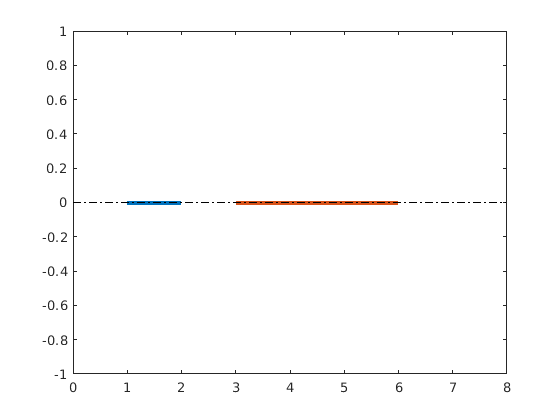

figure
x = linspace(1,2);
y = 3*x;
plot(x,zeros(size(x)),'LineWidth',3)
hold on
plot(y,zeros(size(y)),'LineWidth',3)
xlim([0, 8])
plot(xlim, [0 0],'k-.')

hold off

### Линейная зависимость: двумерный случай

### 
$$A:R^2 \to R^1$$


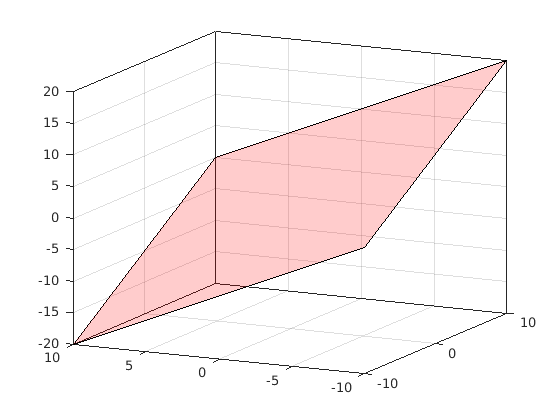

a1 = 1; a2 = -1; 
x = [-10 10 10 -10]; y = [10 10 -10 -10];
[X, Y] = meshgrid(x,y);
z = a1*X + a2*Y;

f = figure;
ax = axes('Parent',f);
ax.View = [-64 15]; 
ax.XGrid = 'on'; ax.YGrid = 'on'; ax.ZGrid = 'on';
ax.Box = 'on'; hold on
C= zeros([size(z),3]);C(:,:,1) = 1;
surf(X,Y,z,C,'facealpha',.2)

### Линейная зависимость: двумерный случай

### 
$$A:R^2 \to R^2$$


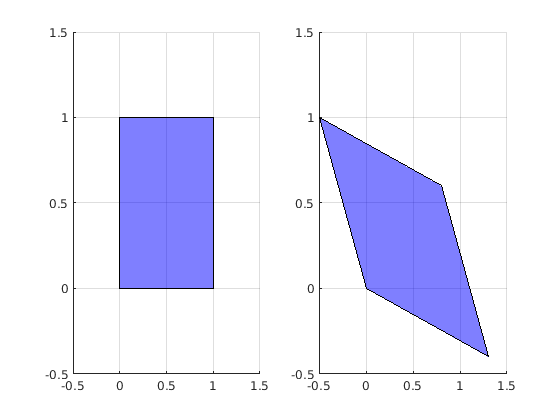

figure
subplot(1,2,1)
ps = patch('XData',[0 0 1 1],'YData',[1 0 0 1],'FaceColor','blue','FaceAlpha',.5);
a = gca;
grid on
a.XLim = [-0.5 1.5]; a.YLim = [-0.5 1.5];

X = ps.Vertices';

% Матрица преобразования
A = [1.3 -0.5; -0.4 1];

Y = A*X;
subplot(1,2,2)
a = gca;
grid on
a.XLim = [-0.5 1.5]; a.YLim = [-0.5 1.5];
hold on
psr = patch('XData',Y(1,:),'YData',Y(2,:),'FaceColor','b','FaceAlpha',.5);

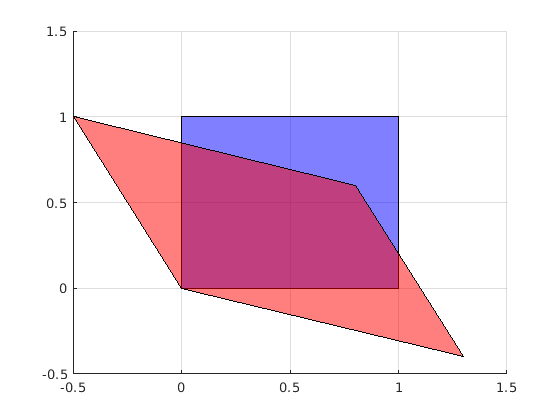

figure

ps = patch('XData',[0 0 1 1],'YData',[1 0 0 1],'FaceColor','blue','FaceAlpha',.5);
a = gca;
grid on
a.XLim = [-0.5 1.5]; a.YLim = [-0.5 1.5];

X = ps.Vertices';

% Матрица преобразования
A = [1.3 -0.5; -0.4 1];

Y = A*X;

grid on
a.XLim = [-0.5 1.5]; a.YLim = [-0.5 1.5];
hold on
psr = patch('XData',Y(1,:),'YData',Y(2,:),'FaceColor','r','FaceAlpha',.5);